## **Vibrating masses**

**Physical system and the equations of motion**

Consider a system of $n$ masses connected by a string with uniform tension $T$ between each mass.

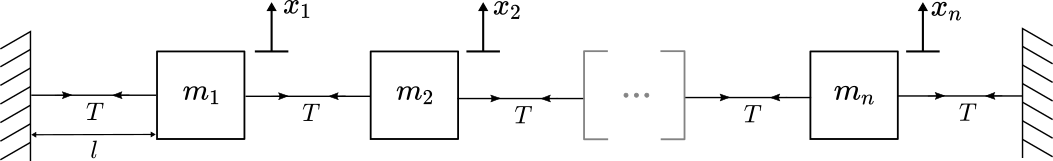

*System of equally spaced connected masses*

Assume additionally that each mass may only be displaced in the vertical direction. You can draw a free body diagram for $i^{th}$ mass and use it to derive the equations of motion.

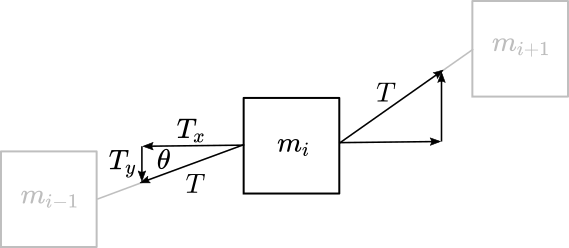

*Free body diagram for the *$i^{th}$* mass*

The angle $\theta$ can be related to the displacements. Note that in this calculation we assume that the displacement is small, so that the horizontal distance between the masses $\approx l$.

    
$$\sin \theta = \frac{x_i - x_{i-1}}{l}$$


The force acting in the $y$-direction is

    
$$\begin{array}{rl} T_y &= T \sin \theta \\ &= \frac{T}{l} (x_i - x_{i-1}) \end{array}$$


Performing the same analysis on the other side of the mass yields a similar result. Applying Newton's second law yields:

    
$$\begin{array}{rl}
m_i \ddot{x}_i &= \frac{T}{l}( - x_i + x_{i-1} )  + \frac{T}{l}(x_{i+1} - x_{i} ) 
\\
m_i \ddot{x}_i &= \frac{T}{l}( x_{i-1} - 2x_i + x_{i+1} )
\end{array}$$


For simplicity of the analysis, assume $m_i = T = l = 1$, yielding:

   
$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


for each mass. Note that for the first and last mass the equations are identical but lack the displacements of the missing neighbor:

   
$$\begin{array}{rl}
\ddot{x}_1 &=  - 2x_i + x_{i+1} 
\\
\ddot{x}_n &=  x_{n-1} - 2x_n 
\end{array}$$


**Matrix form of the equations of motion**

To represent this system in matrix form, define a solution vector

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$.

Then the equations of motion can be written as

    
$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


  **Task. **Define the number of masses in the system (this definition will be used througout the remainder of this example).

n = 5;      % Number of masses
 

** Exercise**. Base on the definition of $\mathbf{x}$ and the ODE

   
$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


what will  the form of $\mathbf{A}$ be in the matrix form of the ODE system, $\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$?

showSolution = false;
if(showSolution)
    AForm(n)
end

** Exercise**. Define the numeric matrix $\mathbf{A$ in MATLAB for an arbitrary number of masses $n$.

  **Pro-tip**: Use the [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) function to create three diagonal matrices and sum the result with the correct coefficients.

% Define the matrix A
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1)

A =     -2     1     0     0     0
     1    -2     1     0     0
     0     1    -2     1     0
     0     0     1    -2     1
     0     0     0     1    -2


**Solution to the ODE system in MATLAB**

The ODE system 

    
$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


is solved here using a numeric ODE solver. In this process, the ODE is integrated to yield a solution $\mathbf{x}(t)$ given a initial conditions $\mathbf{x}(0)$ and $\dot\mathbf{x}(0)$.

  **Task. **Run the section to see the solution. Notice how compact the ODE implementation is by examing the function `odeStringMasses`. Matrix representations, like this one, are particularly useful when writing code.

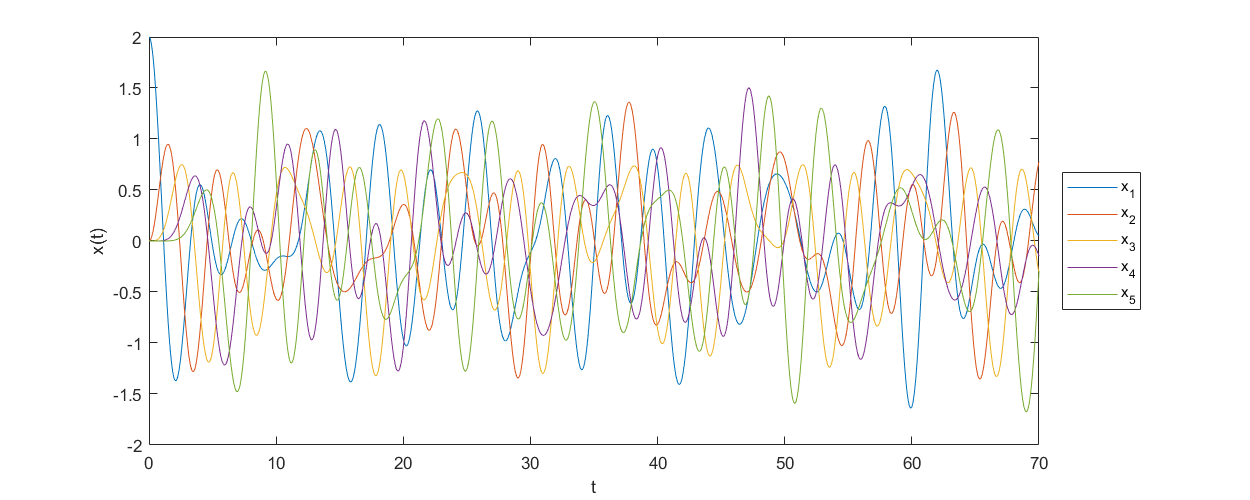

x01 = 2;   % Initial displacement of the first mass
tf =70;     % Duration of the simulation
 

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0,tf]; 
[t,x,xdot] = solveMassesODE(x0, tlim, n);

figure('Position',[100,200,1000,400])
plot(t,x)
xlabel("t")
ylabel("x(t)")
legend("x_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

  **Try**. 

- Adjust the number of masses `n` above and rerun the simulation. Does the natural oscillation frequency change?

- Adjust the initial displacement and duration of the simulation. What happens as $t$ becomes large?

**Visualize the motion**

The graph of displacements can be difficult to relate to physical experience. Try running this section to visualize the motion of the masses.

Nframes = 330; % Adjust the number of frames to speed up or slow down the animation
animateODEMasses(t,x,Nframes)
 

**Eigenvectors and natural oscillation modes**

The natural modes of oscillation of the connected mass system can be identified by computing the eigenvectors of the coefficient matrix.

- Note that these eigenmodes are slightly different than those computed in standard ODEs, but are conceptually similar. These have been selected as they do not require working with the ODE directly.

** Exercise**. Compute the eigen decompoision of $\mathbf{A$ in MATLAB.

% The coefficient matrix
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
% Compute the eigenvectors and eigenvalues
[V,D] = eig(A)

  **Try**. Plot the eigenvectors (the columns of the $\mathbf{V}$ in the eigen decomposition of $\mathbf{A}$) using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#d122e958554) function.

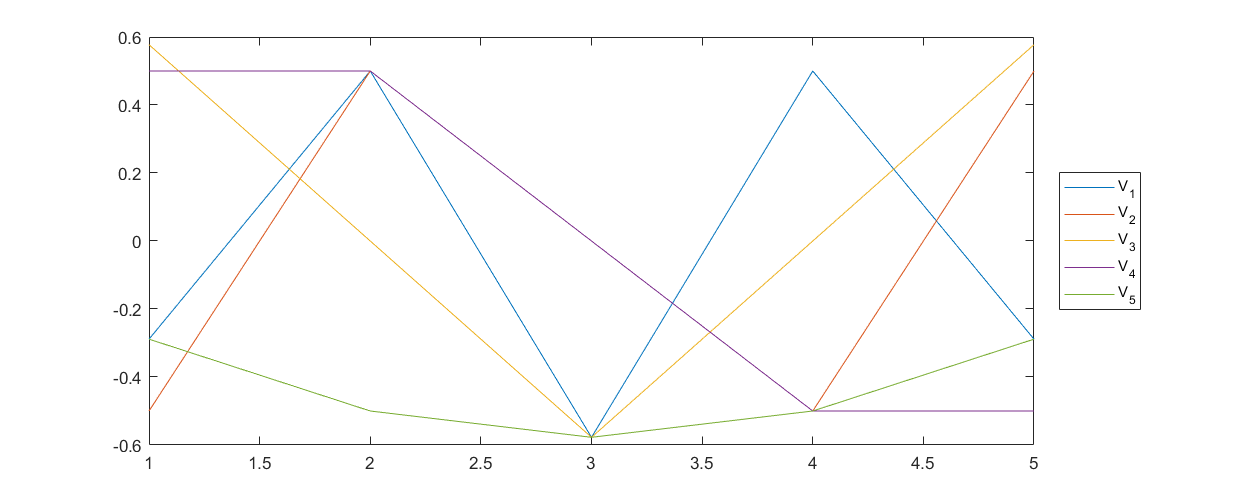

figure('Position',[100,200,1000,400])
% Plot V here
plot(V)

% This adds a legend to the graph
legend("V_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

These eigenvectors actually represent the diplacements of the masses according to a particular natural mode of oscillation. This section visualizes the eigenvectors with the masses shown.

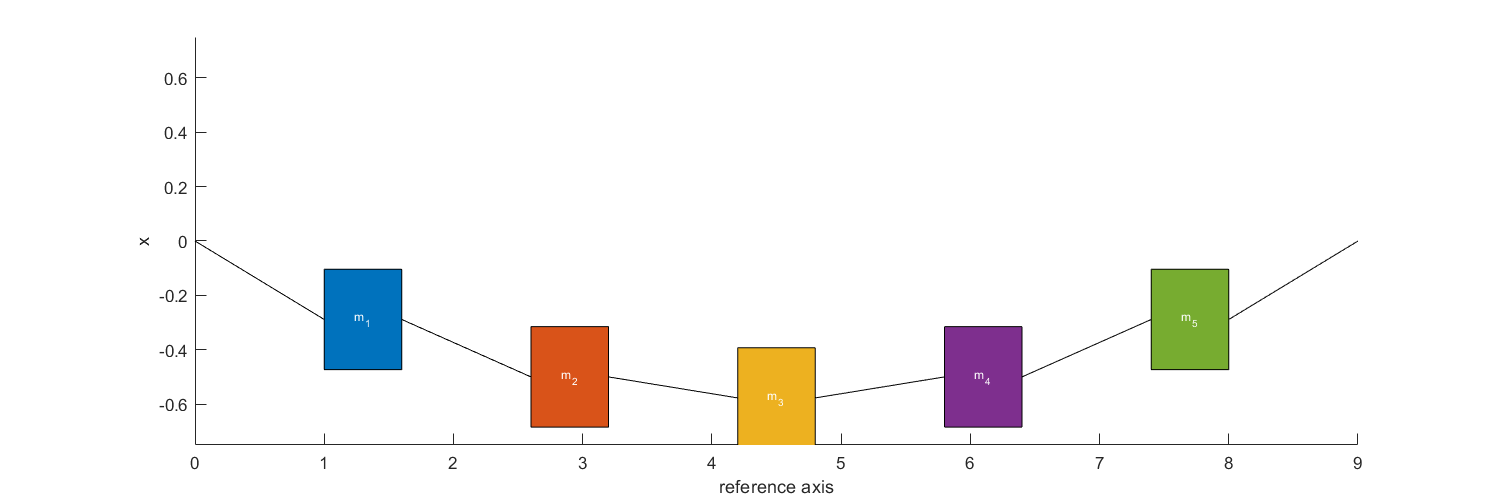

modeIndex = 5; % The mode index must be <= the number of masses
 

visualizeMasses(V(:,modeIndex))

  **Try**. Adjust the mode index to view the natural vibrational modes.

 **Reflect. **Based on the simulation output, which mode do you think is dominant in the simulation generated above?

**Computation of the modes present in the ODE solution**

The eigenvectors provide an alternative basis for the motion of masses. You can compute which mode is dominant for this simulation by expressing the solution in terms of the eigenvector basis:

    
$$\mathbf{x} = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The coefficients $\mathbf{b}$ determine the presence of each mode.

In matrix form:

    
$$\mathbf{x} = \mathbf{V} \mathbf{b}$$


To solve for the mode coefficients, at any time $t$, the matrix solution for $\mathbf{b}$ can be computed.

** Exercise**. Solve for the mode coefficients at the last time step in the simulation. 

  **Pro-tip**: To access the values of $\mathbf{x}$ in the last time step, use:

xf = x(end,:)'

xf =     0.0476
    0.7782
   -0.3171
   -0.1485
   -0.2918


bf = V\xf

bf =     0.5684
    0.2937
    0.0421
    0.6331
   -0.0613


This loop computes the coefficients of the eigenmodes over the whole simulation.

% Compute the coefficients b
b = zeros(size(x));
for k = 1:length(t)
    b(k,:) = V\x(k,:)';
end

  **Try**. Plot the eigenmode coefficients stored in `b` using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#d122e958554) function.

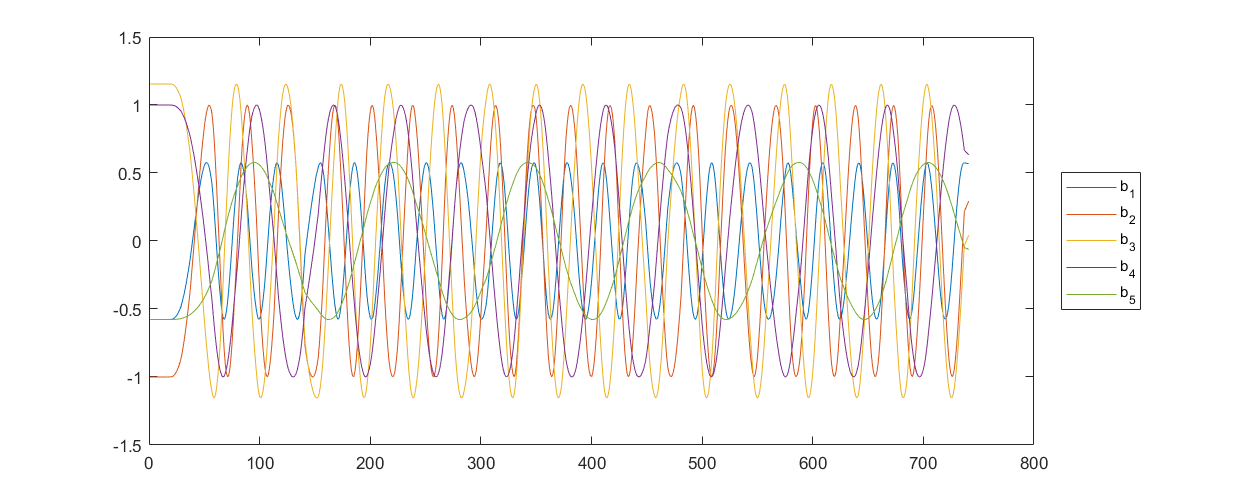

figure('Position',[100,200,1000,400])
% Plot b here
plot(b)

% This adds a legend to the plot
legend("b_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

 **Reflect. **Which mode is dominant?

**Eigenmode solutions**

In this losseless system, an arbitrary solution can be constructed as a sum of the natural oscillation modes. To do so, you can set the inital displacement of the system to a sum of the natural modes:

        
$$\mathbf{x}_0 = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The system will continue to oscillate with those natural modes indefinitely as there is no damping term in the equation. 

  **Task**.  Define the $n$-element mode coefficient vector $\mathbf{b}$ to determine which modes will be present in the simulation. 

b = [0 1 0 0 0]'    

b =      0
     1
     0
     0
     0


  **Task**. Compute the initial condition vector $\mathbf{x}_0$ based on the vector $\mathbf{b}$ and the eigenvector matrix $\mathbf{V}$.

x0 = V*b

x0 =    -0.5000
    0.5000
   -0.0000
   -0.5000
    0.5000


**Visualize the motion**

Run this section to compute the  ODE solution and visualize it.

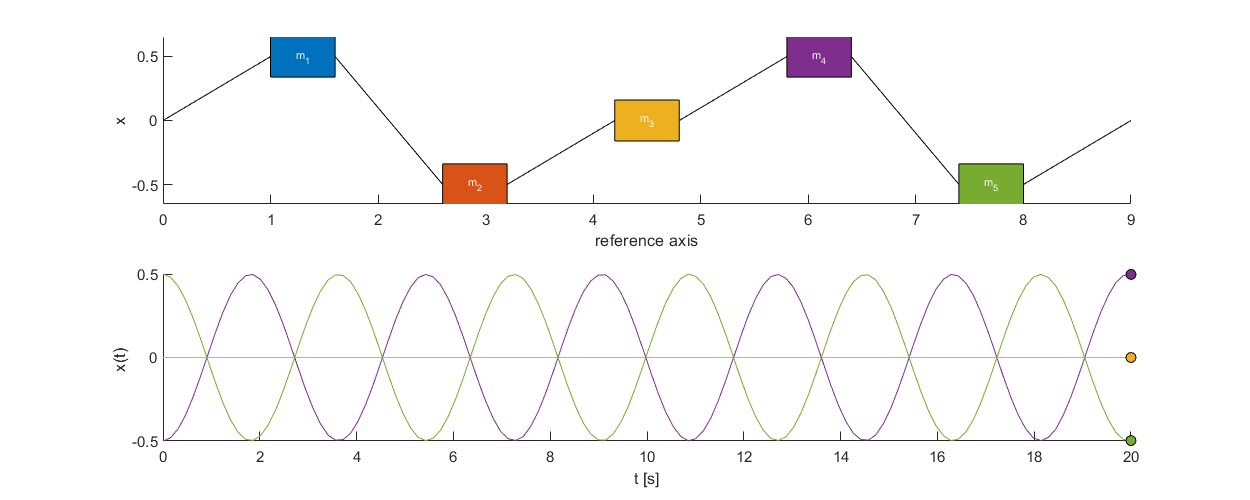

Error using close
Invalid figure handle.

Error in multipleMSDApplication>animateODEMasses (line 129)
    close(f);

tf =20;     % Duration of the simulation
Nframes = 130; % Adjust the number of frames to speed up or slow down the animation
 
tlim = [0,tf]; 
[t,x,xdot] = solveMassesODE(x0, tlim, n);
animateODEMasses(t,x,Nframes)

You can also compute the coefficients of the eigenmodes over time. Run this section to view the coefficients over time.

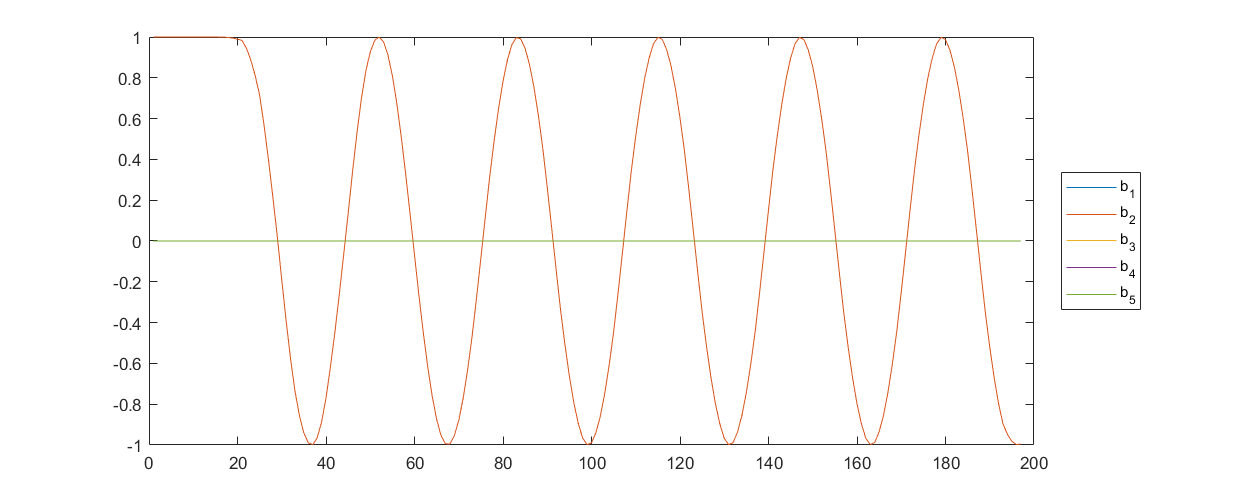

 
% Compute the coefficients b
b = zeros(size(x));
for k = 1:length(t)
    b(k,:) = V\x(k,:)';
end
% Plot them
figure('Position',[100,200,1000,400])
plot(b)
legend("b_{" + strsplit(num2str(1:n)) + "}",'Location','EastOutside')

 **Reflect. **

- Is energy transferred between eigenmodes?

function animateODEMasses(tin,xin,Nframes)
    % This function plots the ODE result
    Nmass = size(xin,2); % Number of masses
    t = linspace(tin(1),tin(end),Nframes);
    x = interp1(tin,xin,t);
    
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*1.3;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    f = figure("Visible","On");    
    set(gcf,'position',[100 200 1200 800])   
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        for k = 1:Nmass
            % Plot masses
            umk = spacing*k -w;
            xm = x(j,k);
            rectangle("Position",[umk x(j,k)-h/2 w h],"FaceColor",colors(k,:))
            text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
                "center","color","w","fontsize",h*20)
            % Plot strings
            if(k == 1)
                plot([umk-spacing+w, umk],[0,x(j,k)],'k')
            else
                plot([umk-spacing+w, umk],[x(j,k-1),x(j,k)],'k')
            end
        end
        % Last string
        umk = umax;
        plot([umk-spacing+w, umax],[x(j,k),0],'k')

        hold off
        axis([0,umax,-xub,xub])
        ylabel("x")
        xlabel("reference axis")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x(t) ")
        hold off
        box off
        drawnow
    end
    close(f);
end

function visualizeMasses(x)
    Nmass = length(x); % Number of masses
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*1.3;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    figure;
    set(gcf,'position',[100 200 1200 400])   
    hold on
    for k = 1:Nmass
        % Plot masses
        umk = spacing*k -w;
        xm = x(k);
        rectangle("Position",[umk x(k)-h/2 w h],"FaceColor",colors(k,:))
        text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
            "center","color","w","fontsize",h*20)
        % Plot strings
        if(k == 1)
            plot([umk-spacing+w, umk],[0,x(k)],'k')
        else
            plot([umk-spacing+w, umk],[x(k-1),x(k)],'k')
        end
    end
    % Last string
    umk = umax;
    plot([umk-spacing+w, umax],[x(k),0],'k')

    hold off
    axis([0,umax,-xub,xub])
    ylabel("x")
    xlabel("reference axis")
end

function [t,x,xdot] = solveMassesODE(x0, tlim, n)
    % This function solves the ODE with n masses
    xdot0 = zeros(n,1);
    y0 = [xdot0;x0];
    
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    odeFunc = @(t,y)odeStringMasses(t,y,A,n);
    [t,y] = ode45(odeFunc,tlim,y0);
    
    xdot = y(:,1:n);
    x = y(:,n+1:2*n);
end

function [dydt] = odeStringMasses(t,y,A,n)
    % The second order system has been reduced to a system of first order
    % equations: the variable y =[u;x] where u = x_dot.
    u = y(1:n);
    x = y(n+1:2*n);
    x_dot = u;
    u_dot = A*x;
    dydt = [u_dot; x_dot];    
end

function AForm(n)
    A = sym(diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1))
end

% Suppress unused suggestions
%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT> 